# State Signal Preperation File

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 27/07/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

Set path to function folder

% Add /functions directory 
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/dataprocessing/functions/'));

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Data Manipulation/',exportName);

Set Prepared data export path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/', exportName);

**Set Directories & Load Data**

Load Signal data

% use your default user path to create the filename and path
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'))
load 'DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat';

## 2. Custom Signal Construction

2.1 ROLLING RETURNS:

- SA Equity Momentum: Calculate 12 month rolling returns of JALSH

2.2 COMPOSIT INDICES:

- Equity Risk Premium (USA - SA) 

- EQT_RISK_PREM =  (SPX-US003M)-(JALSH-JIBA3M)

### 2.1 Rolling Returns for SA Equity **Momentum** (12 month RR of JALSH)

% Divide each element in each column of x by the first element of that column
JALSH_TT = SIG_aligned_dataTable(:,'JALSHTR_Index');
% Can adjust the calmonths(x) arg to specify period of Rolling Returns.
JALSH_12M_RR = table2array(rollingreturns(JALSH_TT, 'Period', calmonths(12), 'EndOfMonth', true, 'Method','continuous'));

% Rolling Returns as Momentum
SIG_aligned_dataTable.JALSH_12M_RR = JALSH_12M_RR;

### 2.2 Construction pre-smoothing

#### Composit index for Equity Risk Premium (USA - SA) 

EQT_RISK_PREM =  (SPX-US003M)-(JALSH-JIBA3M)

Pre_smoother_EQT_RISK_PREM = (SIG_aligned_dataTable.SPX_Index-SIG_aligned_dataTable.US0003M_Index)-(SIG_aligned_dataTable.JALSHTR_Index-SIG_aligned_dataTable.JIBA3M_Index);
SIG_aligned_dataTable.Pre_EQT_RISK_PREM = Pre_smoother_EQT_RISK_PREM;

## 3. Variable Smoothing using Meucci Double Decay

### 3.1 Apply Soothing to all

Trend SMOOTHING

Use a double decay method (Holt’s linear method) to smooth varaibles to reduce noise. 

fas_hl = 3;
slow_hl = 3*12;
[SIG_SMOOTHED_TT, test_z, test_mu] = timetable_Ddecay(SIG_aligned_dataTable, fas_hl, slow_hl);

### 3.2 Visualising the level and trend adjustment of USDZAR when applying Double Decay as an example

USDZAR_raw = timetable(SIG_aligned_dataTable.Dates, SIG_aligned_dataTable.USDZAR_Curncy);
[USDZAR_smoothed, USDZAR_z1, USDZAR_z2] = timetable_Ddecay(USDZAR_raw, fas_hl, slow_hl);

% cut raw to match length of z1 and z2
% Get the height of the array
z1Height = size(USDZAR_z1, 2);
% Cut the timetable object to match the height of the array
USDZAR_raw_cut = USDZAR_raw(1:z1Height, :);
% Add variables to plot
USDZAR_raw_cut.z_level = USDZAR_z1';
USDZAR_raw_cut.z_trend = USDZAR_z2';
USDZAR_raw_cut.z_standardised = USDZAR_smoothed.Var1(1:z1Height, :);

#### 3.2.1 Check smoothing with an example variable to plot

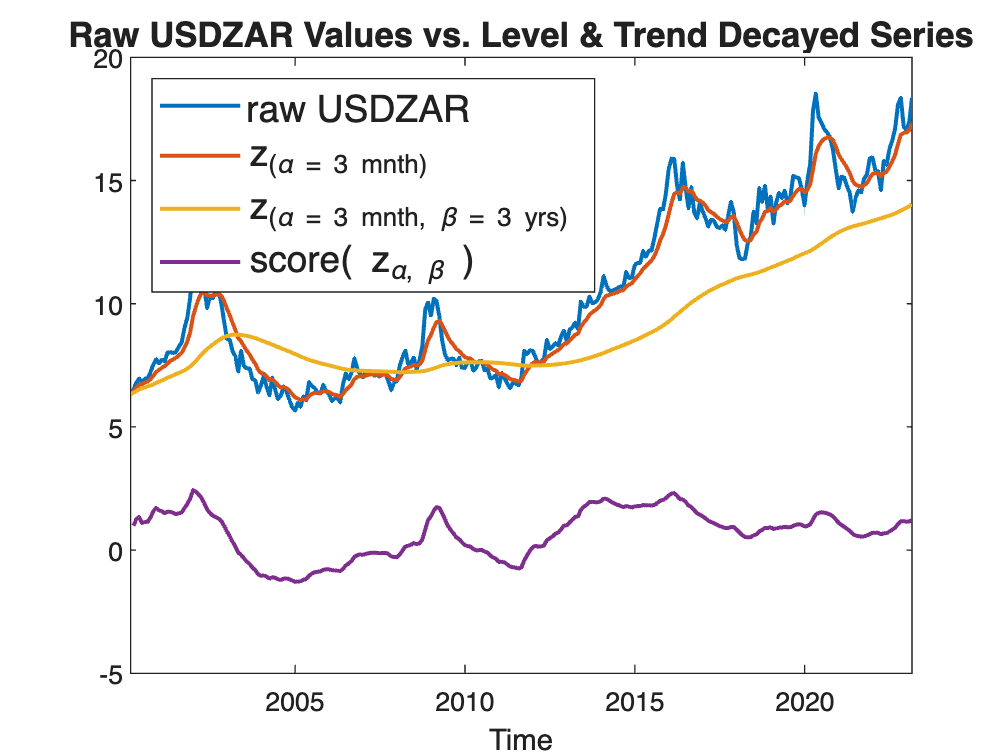

% Create a new figure
plot(USDZAR_raw_cut.Time, USDZAR_raw_cut.Variables,'LineWidth', 1.5)
title("Raw USDZAR Values vs. Level & Trend Decayed Series",'FontSize', 13);
xlabel('Time')
ylabel('')
legend('raw USDZAR', 'z_{(\alpha = 3 mnth)}', 'z_{(\alpha = 3 mnth, \beta = 3 yrs)}', 'score( z_{\alpha, \beta} )','Location', 'northwest','FontSize', 14)

SIG_USDZAR_DDecay_zSeries_plot = gca;


#### **Export Nomralised Smoothed Signal Plot**

exportName = 'SIG_USDZAR_DDecay_zSeries_plot.pdf';
exportgraphics(SIG_USDZAR_DDecay_zSeries_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

## 4. Smoothed Signal Manipulation

4.1 LAG Adjustments:

- CPI lag by 1 month

- Money supply lag by 1 month

- GDP lag by 3 months

- 'OECD' Leading indicator by 6 months

4.2 Construction Post-smoothing

Composit index for Equity Risk Premium (USA - SA) 

EQT_RISK_PREM =  (SPX-US003M)-(JALSH-JIBA3M)

### 4.1 Lag CPI and Money supply Indicators by 1 month to account for delay in information.

% varaibles to lag: SACPIYOY_Index & SAMYM3Y_Index
% Lag {'SACPIYOY_Index', 'SAMYM3Y_Index'} by 1 timestamp
lagged_SACPIYOY_Index = [NaN; SIG_SMOOTHED_TT.SACPIYOY_Index(1:end-1)];
lagged_SAMYM3Y_Index = [NaN; SIG_SMOOTHED_TT.SAMYM3Y_Index(1:end-1)];

GDP (3 mnth)

% Lag GDP {SAGDP_M_INTERPOLATED} by 3 months
lagged_SAGDP_Index = [NaN(3, 1); SIG_SMOOTHED_TT.SAGDP_M_INTERPOLATED(1:end-3)];

'OEZAKLAP_Index' (6 mnth)

% Lag GDP {SAGDP_M_INTERPOLATED} by 6 months
lagged_OEZAKLAP_Index = [NaN(6, 1); SIG_SMOOTHED_TT.OEZAKLAP_Index(1:end-6)];

#### 4.1.1 Replace original vars with Adjusted 

% Add the lagged variables as columns to SIG_aligned_dataTable
SIG_SMOOTHED_TT.lagged_SACPIYOY_Index = lagged_SACPIYOY_Index;
SIG_SMOOTHED_TT.lagged_SAMYM3Y_Index = lagged_SAMYM3Y_Index;
SIG_SMOOTHED_TT.lagged_SAGDP_Index = lagged_SAGDP_Index;
SIG_SMOOTHED_TT.lagged_OEZAKLAP_Index = lagged_OEZAKLAP_Index;


% move original cols to end of TT
SIG_SMOOTHED_TT = movevars(SIG_SMOOTHED_TT,{'JALSHTR_Index','SACPIYOY_Index', 'SAMYM3Y_Index', 'SAGDP_M_INTERPOLATED','OEZAKLAP_Index'},'After',width(SIG_SMOOTHED_TT));

New timetable with only lagged values

SIG_SMOOTHED_TT = SIG_SMOOTHED_TT(:, setdiff(SIG_SMOOTHED_TT.Properties.VariableNames, {'SACPIYOY_Index', 'SAMYM3Y_Index', 'SAGDP_M_INTERPOLATED','OEZAKLAP_Index'}));

### 4.2 Composit index for Equity Risk Premium (USA - SA) 

EQT_RISK_PREM =  (SPX-US003M)-(JALSH-JIBA3M)

post_smoothed_EQT_RISK_PREM = (SIG_SMOOTHED_TT.SPX_Index-SIG_SMOOTHED_TT.US0003M_Index)-(SIG_SMOOTHED_TT.JALSHTR_Index-SIG_SMOOTHED_TT.JIBA3M_Index);
SIG_SMOOTHED_TT.post_EQT_RISK_PREM = post_smoothed_EQT_RISK_PREM;

Remove: SPX, US0003M, JALSH, JIB3M

SIG_SMOOTHED_TT = SIG_SMOOTHED_TT(:, setdiff(SIG_SMOOTHED_TT.Properties.VariableNames, {'SPX_Index', 'US0003M_Index', 'JALSHTR_Index','JIBA3M_Index'}));

#### CLEAN UP:

[countNans,idx] = max(sum(isnan(SIG_SMOOTHED_TT{:,:}),1));
rmmissingProxy =  SIG_SMOOTHED_TT.Properties.VariableNames{idx};
SIG_SMOOTHED_TT = rmmissing(SIG_SMOOTHED_TT,"DataVariables",rmmissingProxy);
% spy(transpose(isnan(table2array(SIG_SMOOTHED_TT))));

## 5. Visualisations

### 5.1 Plot smoothed standardised data 

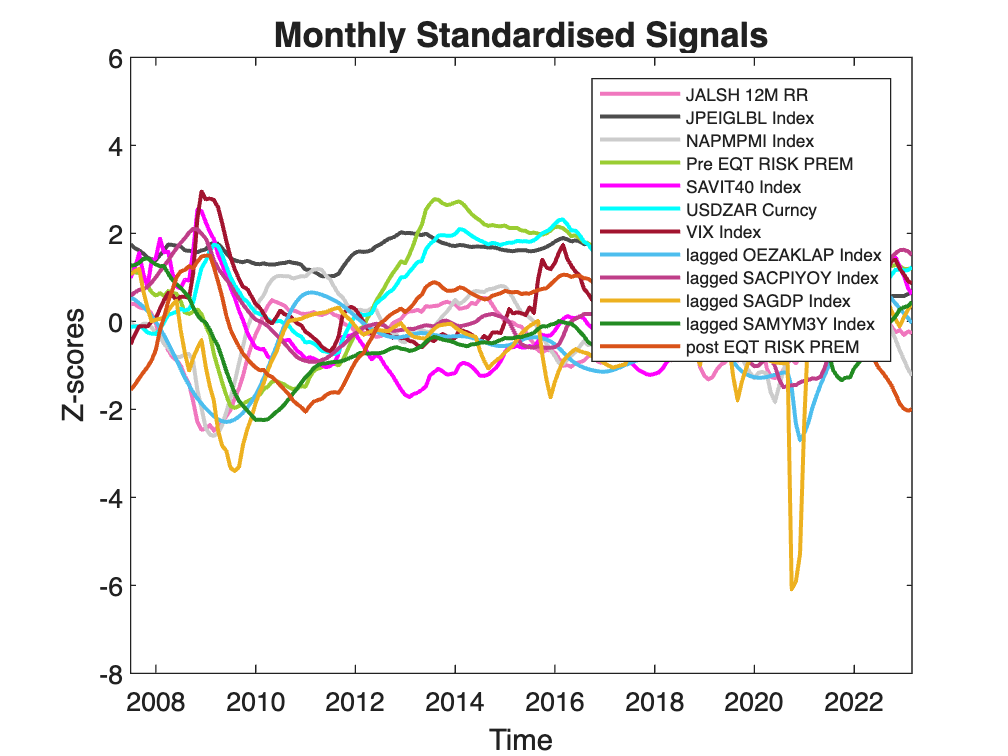

% rename the variables with underscores instead of spaces
SIG_PlotNames = strrep(SIG_SMOOTHED_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
SIG_PlotNames = strrep(SIG_PlotNames, 'TR', '');

colors = [
    0.8500 0.3250 0.0980;    % Orange
    0.1333 0.5451 0.1333;    % Forest green
    0.9290 0.6940 0.1250;    % Coral
    0.7490 0.2431 0.5373;    % Violet
    0.3010 0.7450 0.9330;    % Light Blue
    0.6350 0.0780 0.1840;    % Red
    0 1 1;                   % Cyan
    1 0 1;                   % Magenta
    0.6039 0.8039 0.1961;    % Yellow-Green
    0.8 0.8 0.8;             % Light Gray
    0.3 0.3 0.3;             % Dark Gray
    0.9412 0.4667 0.7451     % New color (Light Pink)
];

figure;
plot(SIG_SMOOTHED_TT.Time, table2array(SIG_SMOOTHED_TT), 'LineWidth', 1.5);
ylabel("Z-scores");
xlabel("Time");
title("Monthly Standardised Signals",'FontSize', 13);
legend(SIG_PlotNames, 'Location', 'northeast', 'FontSize', 6.5); % Decrease the font size
SIG_prep_TT_plot = gca;

% Assign colors to each line
for i = 1:numel(SIG_prep_TT_plot.Children)
    SIG_prep_TT_plot.Children(i).Color = colors(i, :);
end
hold off;

#### **Export Nomralised Smoothed Signal Plot**

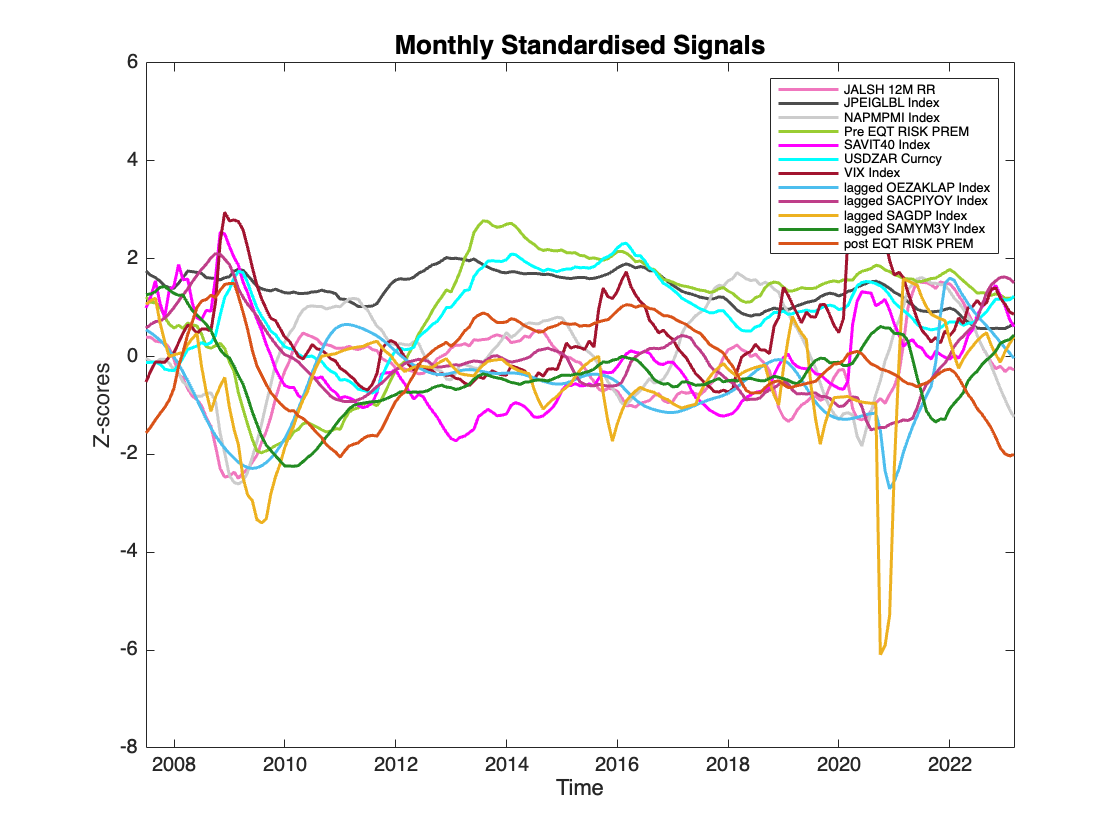

exportName = 'SIG_norm_smoothed_plot.pdf';
exportgraphics(SIG_prep_TT_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

### **5.2 Explore Trends across signals**

**We see multiplicative trend and potentially mltiplicative seasonality (not extremely strong but can test for it) for EQ Risk Premium Diff.**

Remember that exponential smoothing removes trends but DDecay mainly works for additive trend and no seasonality

This suggests we need to use another method to smooth this as it is a mu;tiplicative exponential trend 

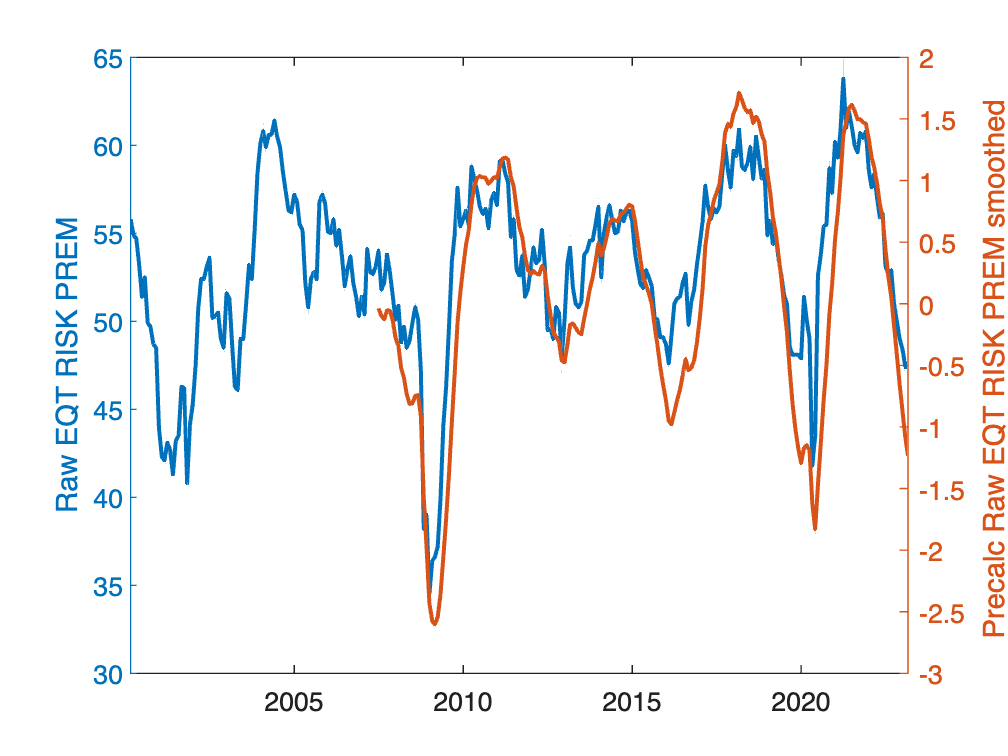

figure;
yyaxis left;
plot(SIG_aligned_dataTable.Dates, SIG_aligned_dataTable.NAPMPMI_Index, 'LineWidth', 1.5);
% yline(-1.04, 'r--','Label', 'z*');
ylabel('Raw EQT RISK PREM');
title('');

yyaxis right;
plot(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.NAPMPMI_Index, 'LineWidth', 1.5);
% yline(-1.04, 'r--','Label', 'z*');
ylabel('Precalc Raw EQT RISK PREM smoothed ');

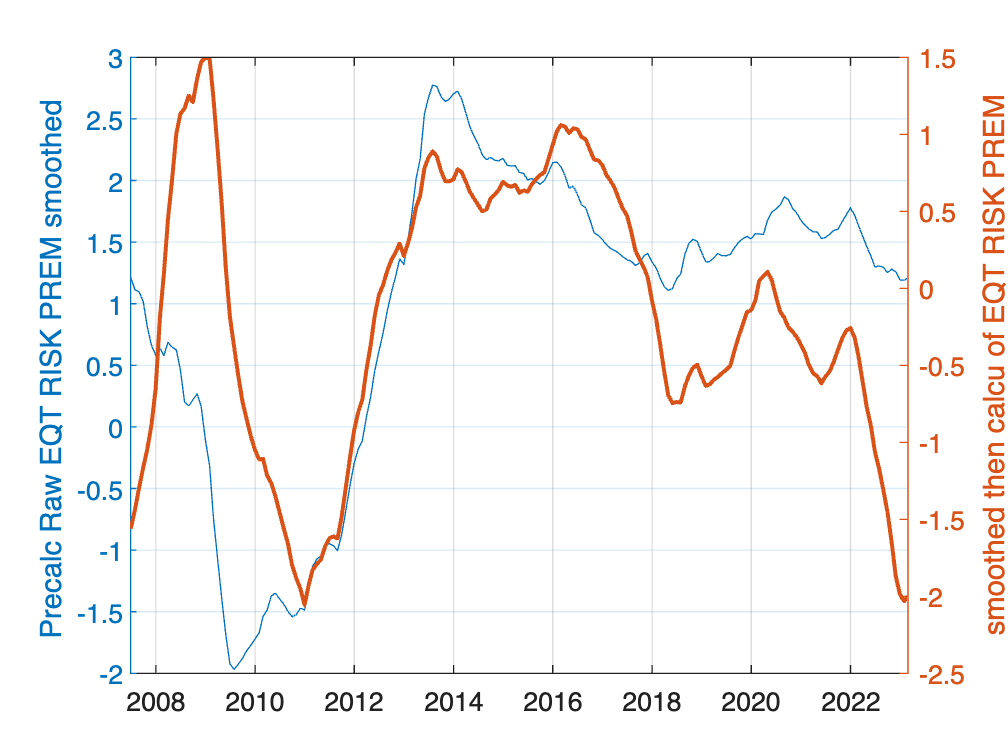

% Create a new figure
figure;

yyaxis left;
plot(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.Pre_EQT_RISK_PREM);
ylabel('Precalc Raw EQT RISK PREM smoothed ');

yyaxis right;
plot(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.post_EQT_RISK_PREM, 'LineWidth', 1.5);
% yline(-1.04, 'r--','Label', 'z*');
ylabel('smoothed then calcu of EQT RISK PREM');

pre_post_EQR_RISK_PRE_comp = gca;

% Adjust the appearance of the plot
grid on;

#### **Export Nomralised Smoothed Signal Plot**

exportName = 'pre_post_EQR_RISK_PRE_comp.pdf';
exportgraphics(pre_post_EQR_RISK_PRE_comp, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

### 5.3 Comparison of raw vs lagged: CPI

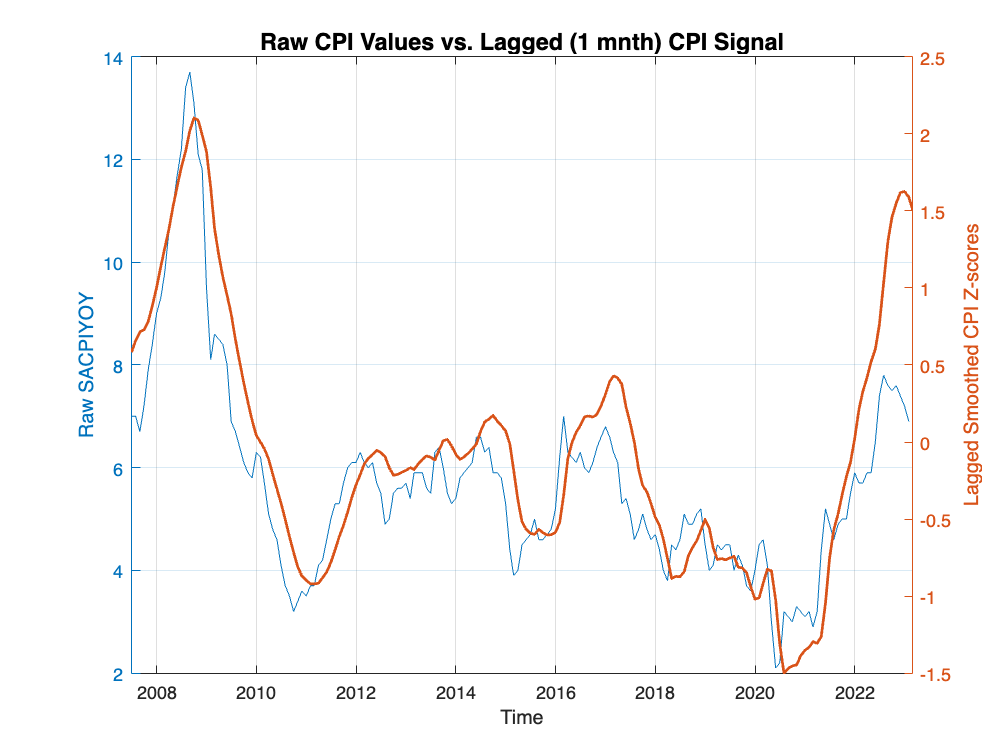

% Find the start date of SIG_SMOOTHED_TT.Time
start_date = SIG_SMOOTHED_TT.Time(1);
end_date = SIG_SMOOTHED_TT.Time(end);

% Cut SIG_aligned_dataTable at the start date
time_range = timerange(start_date, end_date);
cut_SIG_aligned_dataTable = SIG_aligned_dataTable(time_range,:);

% Create a new figure
figure;
title("Raw CPI Values vs. Lagged (1 mnth) CPI Signal",'FontSize', 13);

yyaxis left;
plot(cut_SIG_aligned_dataTable.Dates, cut_SIG_aligned_dataTable.SACPIYOY_Index);
ylabel('Raw SACPIYOY');
% Set x-axis range from the first date to the end
xlim([SIG_SMOOTHED_TT.Time(1), SIG_SMOOTHED_TT.Time(end)]);
yyaxis right;
plot(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index, 'LineWidth', 1.5);
% yline(-1.04, 'r--','Label', 'z*');
ylabel('Lagged Smoothed CPI Z-scores');

% Set x-axis range from the first date to the end
xlabel("Time")
xlim([SIG_SMOOTHED_TT.Time(1), SIG_SMOOTHED_TT.Time(end)]);

% Adjust the appearance of the plot
grid on;

SIG_CPI_raw_zscore_plot = gca;

### 5.4 Comparison of raw vs lagged: GDP

% Create a new figure
figure;
title("Raw Domestic Leading Indicator vs. Lagged (6mths) Signal",'FontSize', 13);

yyaxis left;
plot(cut_SIG_aligned_dataTable.Dates, cut_SIG_aligned_dataTable.OEZAKLAP_Index);
ylabel('Raw Domestic Leading Indicator');
% Set x-axis range from the first date to the end
xlim([SIG_SMOOTHED_TT.Time(1), SIG_SMOOTHED_TT.Time(end)]);
yyaxis right;
plot(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.lagged_OEZAKLAP_Index, 'LineWidth', 1.5);
% yline(-1.04, 'r--','Label', 'z*');
ylabel('Lagged Smoothed Z-scores');

% Set x-axis range from the first date to the end
xlabel('Time')
xlim([SIG_SMOOTHED_TT.Time(1), SIG_SMOOTHED_TT.Time(end)]);

% Adjust the appearance of the plot
grid on;
SIG_DomesticIndicator_raw_zscore_plot = gca;


#### **Export CPI Example Smoothed Signal Plot**

exportName = 'SIG_CPI_raw_zscore_plot.pdf';
exportgraphics(SIG_CPI_raw_zscore_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

#### **Export Domestic Indicator Example Smoothed Signal Plot**

exportName = 'SIG_DomesticIndicator_raw_zscore_plot.pdf';
exportgraphics(SIG_DomesticIndicator_raw_zscore_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

SIG_SMOOTHED_TT.Properties.VariableNames

ans = 1×12 cell array
    {'JALSH_12M_RR'}    {'JPEIGLBL_Index'}    {'NAPMPMI_Index'}    {'Pre_EQT_RISK_PREM'}    {'SAVIT40_Index'}    {'USDZAR_Curncy'}    {'VIX_Index'}    {'lagged_OEZAKLAP_Index'}    {'lagged_SACPIYOY_Index'}    {'lagged_SAGDP_Index'}    {'lagged_SAMYM3Y_Index'}    {'post_EQT_RISK_PREM'}


#### **SAVE Log Diff Returns Datasets:**

**TO DO: Use data_cleaning_001 to auto assign date range to file names (will code later)**

4.1 LAG Adjustments:

- CPI lag by 1 month

- Money supply lag by 1 month

- GDP lag by 3 months

- 'OECD' Leading indicator by 6 months

SIG_SMOOTHED_TT.Properties.Description = ['Processed State Signals SMOOTHED: ' num2str(fas_hl) ' mths fast half life & ' num2str(slow_hl) ' mths slow half life. Frequency: MONTHLY. Last Updated: Aug23. Original Source: Bloomberg. Intended file naming: DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat'];
SIG_SMOOTHED_TT.Properties.VariableDescriptions = {'ALSI 12M rolling returns as Market Momentum Proxy', ...
    'JP Morgan Emerging Markets Bond Index (EMBI)',...
    'SA Manufacturing Purchasing Managers, Index (PMI)',...
    'US/SA Risk Premium (before variable smoothing)', ...
    'SA Volatility Index',...
    'US/SA Currency Exchange Rate',...
    'US Volatility Index',...
    '6 mth lagged SA Domestic Leading Indicator',...
    '1 mth lagged SA Year of Year CPI',...
    '3 mth lagged SA GDP',...
    '1 mth lagged SA Money Supply',...
    'US/SA Risk Premium (after variable smoothing)'};

SIG_SMOOTHED_TT.Properties

ans =   TimetableProperties with properties:

             Description: 'Processed State Signals SMOOTHED: 3 mths fast half life & 36 mths slow half life. Frequency: MONTHLY. Last Updated: Aug23. Original Source: Bloomberg. Intended file naming: DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat'
                UserData: []
          DimensionNames: {'Time'  'Variables'}
           VariableNames: {1×12 cell}
    VariableDescriptions: {1×12 cell}
           VariableUnits: {}
      VariableContinuity: []
                RowTimes: [189×1 datetime]
               StartTime: 30-Jun-2007
              SampleRate: NaN
                TimeStep: NaN
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


**Here SMTH-3M3Y denotes the half-lives used for the data smoothing**

exportName = 'DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat';
save(fullfile(dataExportpath,exportName),'SIG_SMOOTHED_TT');